%% 0130 data_process

clear all clc;

x = 255:955;


fileName01 = 'D:/Data/matlab/Spectrum0124/FinalData1/OA/OA300/OA300COS5s';
fileName02 = 'D:/Data/matlab/Spectrum0124/FinalData1/OA/OA300/OA300bg';

fileName03 = 'D:/Data/matlab/Spectrum0124/FinalData1/OA/OA300/OA300mkCOS5s';
%%%%% Sample  %%%%%
filemNums = 8;
ldsNums = zeros(filemNums,1);
for ii = 1:filemNums
    if(ii<10)
        filenameSpe(ii,:) = strcat(fileName01,'0',num2str(ii),'.sif');
        filenameImg(ii,:) = strcat(fileName01,'0',num2str(ii),'.tiff');
        filenameImgMk(ii,:) = strcat(fileName03,'0',num2str(ii),'.tif');
        filenameCsv(ii,:) = strcat(fileName01,'0',num2str(ii),'.csv');

        filenameBg(ii,:) = strcat(fileName02,'0',num2str(ii),'.sif');
    else
        filenameSpe(ii,:) = strcat(fileName01,num2str(ii),'.sif');
        filenameImg(ii,:) = strcat(fileName01,num2str(ii),'.tiff');
        filenameImgMk(ii,:) = strcat(fileName03,num2str(ii),'.tif');
        filenameCsv(ii,:) = strcat(fileName01,num2str(ii),'.csv');

        filenameBg(ii,:) = strcat(fileName02,num2str(ii),'.sif');
    end
end

for ii = 1:filemNums
    RawSpectrumTemp = ReadAndorSIF(filenameSpe(ii,:));
    RawSpectrum(ii) = {RawSpectrumTemp(x,:)};
    Pos{ii} = csvread(filenameCsv(ii,:));
    Img{ii} = imread(filenameImg(ii,:));
    ImgMk{ii} = imread(filenameImgMk(ii,:));
    ldsNums(ii) = size(RawSpectrumTemp,2);
    
    BgTemp = ReadAndorSIF(filenameBg(ii,:));
    BgTemp = cosmic_ray(BgTemp',10,0)';
    BgTemp = mean(BgTemp(x,:),2);
    Bg(ii) = {BgTemp};
end

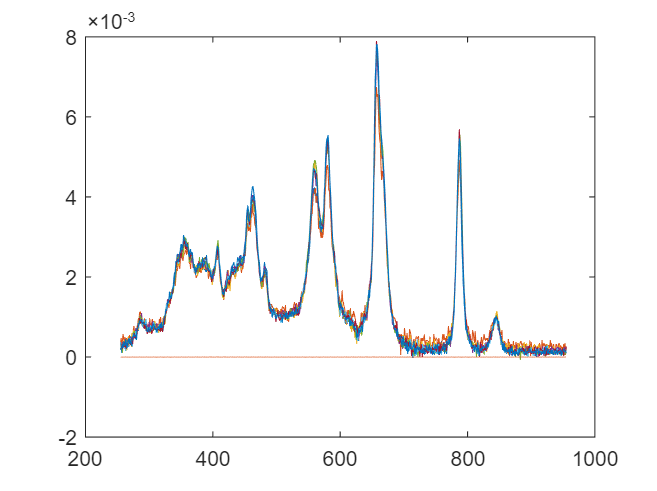

%%%% Remove Bg %%%%
figure
for ii0 = 1: filemNums%filemNums
    ldsTemp = RawSpectrum{ii0};

    Pure = [Bg{ii0},mypoly(0,length(x))'];
    xas = zeros(ldsNums(ii0),size(Pure,2));
    for ii = 1:size(ldsTemp,2)
        xas(ii,:) = asls(Pure,ldsTemp(:,ii),0.001, []);
    end
    Abg = Pure*xas';
    ldsSpec{ii0} = ldsTemp - Abg;
    
    plot(x,mean(ldsTemp - Abg,2)./sum(mean(ldsTemp - Abg,2),'all'))
    hold on;
end
plot(x,zeros(size(x,2),1),'LineWidth',0.5)

for ii = 1:filemNums
    Spetemp = RawSpectrum(ii);
    Spetemp = Spetemp{1,1};

    Imgtemp = Img(ii);
    Imgtemp = Imgtemp{1,1};
    ImgMktemp = ImgMk(ii);
    ImgMktemp = ImgMktemp{1,1};

    Postemp = Pos(ii);
    Postemp = Postemp{1,1};
    for ii1 = 1: size(Spetemp,2)
       if(ImgMktemp(Postemp(ii1,2)+1,Postemp(ii1,3)+1)==0)
            Postemp(ii1, 8) = 0;
       else
            Postemp(ii1, 8) = 1;
       end
       Postemp(ii1,9) = 104;
    end
    Index(ii) = {Postemp};

%     figure
%     imshow(Imgtemp,[])
%     hold on;
%     for ii2 = 1: size(Spetemp,2)
%         if(Postemp(ii2, 8) == 0)
%             plot(Postemp(ii2,2)+1,Postemp(ii2,3)+1,'o',"LineWidth",1.2,"Color",[1,1,0]);
%         end
%     end

end


save('SpectOA300.mat',"ldsSpec","Img","Index")